%% MIT-BIH Arrhythmia Database QRS Complex Detection (All-in-One Script)
% This script contains all necessary functions and analysis code to detect
% QRS complexes in the MIT-BIH Arrhythmia Database using Pan-Tompkins algorithm.

clear;
close all;
clc;s

% Configuration
record_numbers = [100, 101, 103, 105, 106, 109]; % Records to analyze
lead_number = 1;          % ECG lead to analyze (1 or 2)
start_time = 60;          % Start time in seconds (skip first minute)
duration = 60;            % Duration in seconds (analyze one minute)
plot_individual = true;   % Plot individual record results
fs = 360;                 % MIT-BIH sampling frequency

%% Check for WFDB Toolbox
if ~exist('rdann', 'file') || ~exist('rdsamp', 'file')
    error(['WFDB Toolbox not found. Please install it from: ' ...
           'https://physionet.org/content/wfdb-matlab/0.10.0/']);
end

%% Validate that database files exist
try
    
    [test_signal, ~, ~] = rdsamp('mitdb/100', 1, 10, 0);
catch
    error(['Could not access MIT-BIH database files. Please ensure they are downloaded and ' ...
           'properly placed in a "mitdb" folder in your MATLAB path or current directory.']);
end

fprintf('MIT-BIH database is accessible. Proceeding with analysis...\n');

MIT-BIH database is accessible. Proceeding with analysis...



Processing record 100 (1 of 6)...


Loaded record 100: 21601 samples at 360 Hz


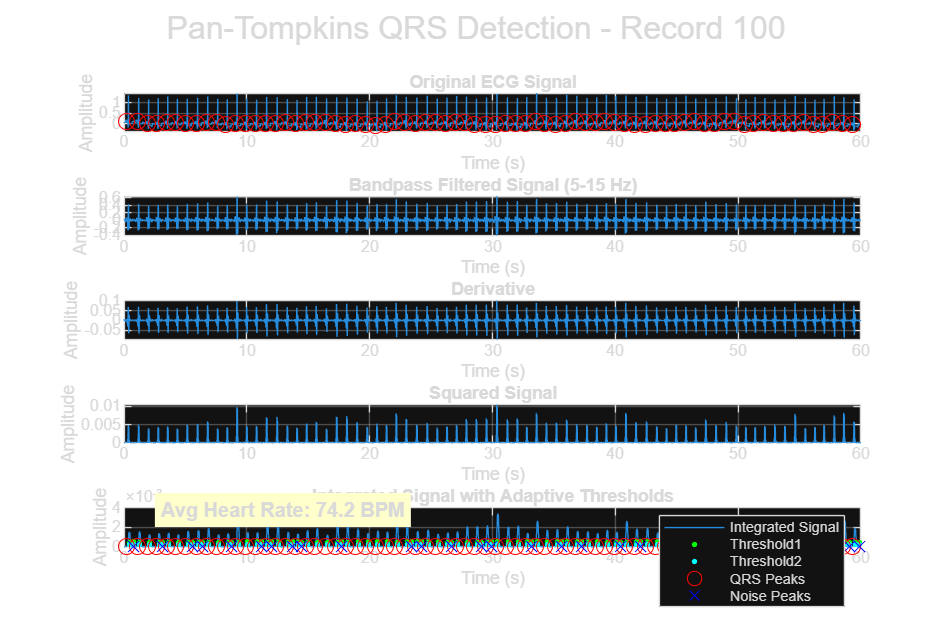


Processing record 101 (2 of 6)...


Loaded record 101: 21601 samples at 360 Hz


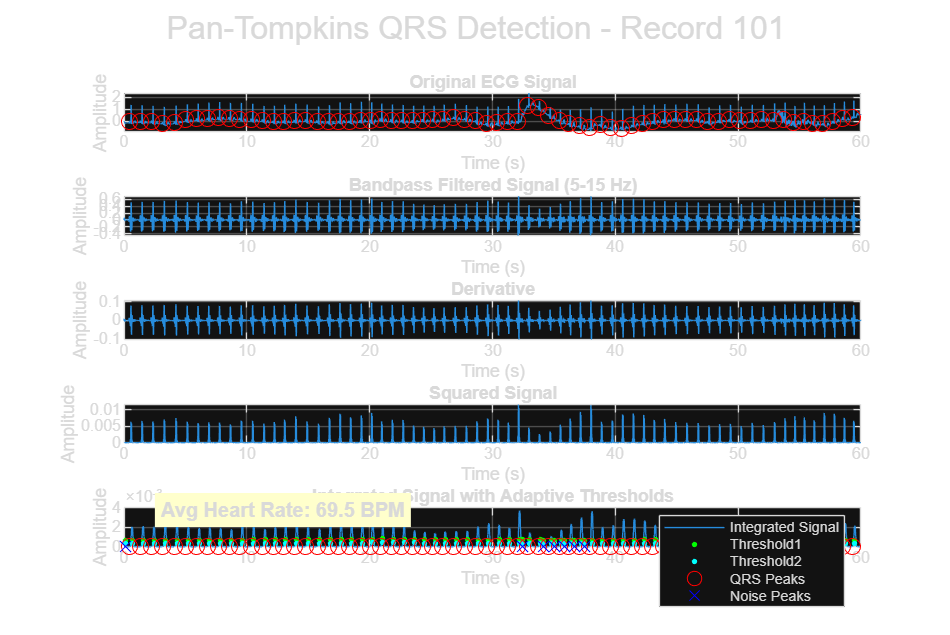


Processing record 103 (3 of 6)...


Loaded record 103: 21601 samples at 360 Hz


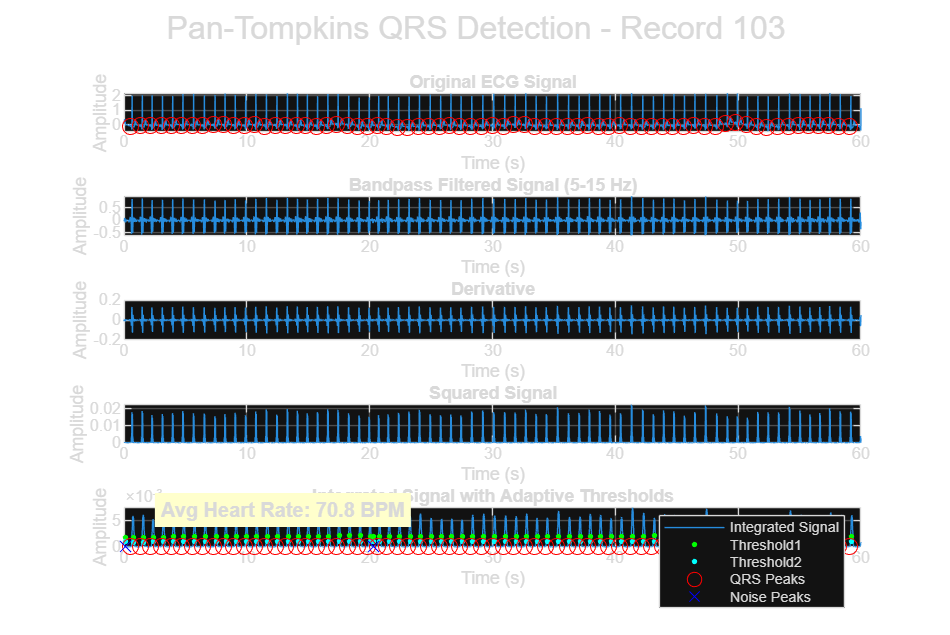


Processing record 105 (4 of 6)...


Loaded record 105: 21601 samples at 360 Hz


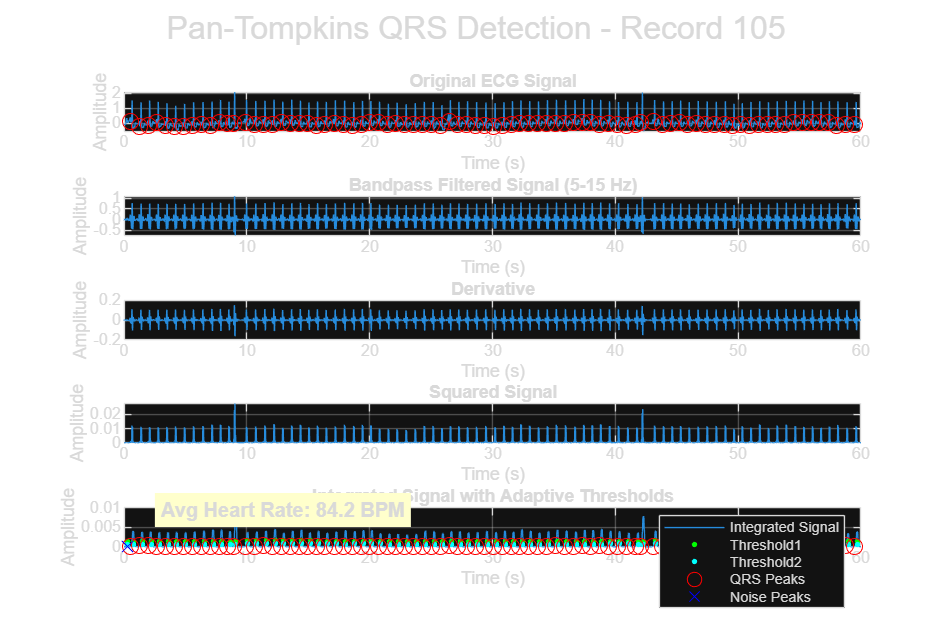


Processing record 106 (5 of 6)...


Loaded record 106: 21601 samples at 360 Hz


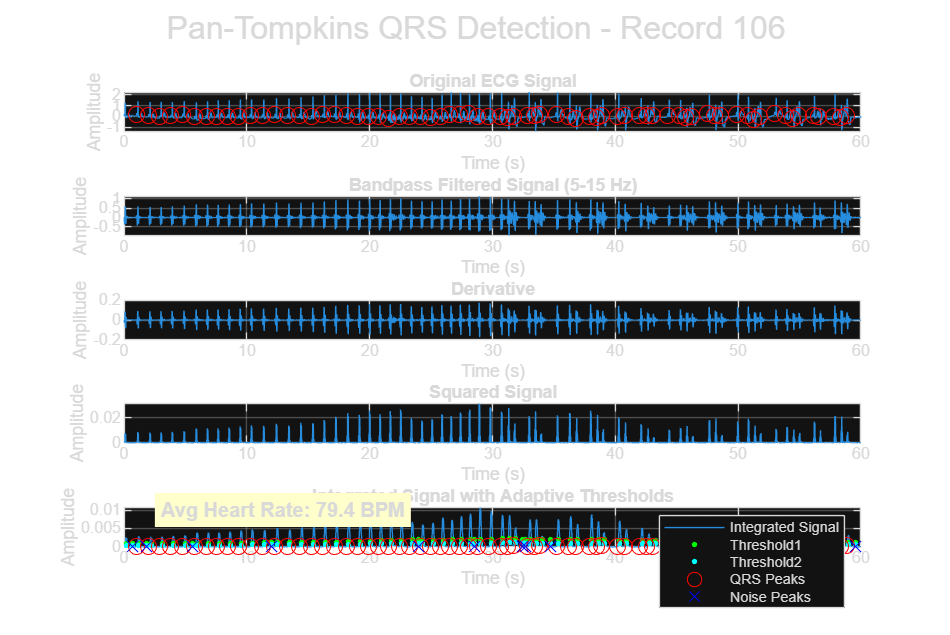


Processing record 109 (6 of 6)...


Loaded record 109: 21601 samples at 360 Hz


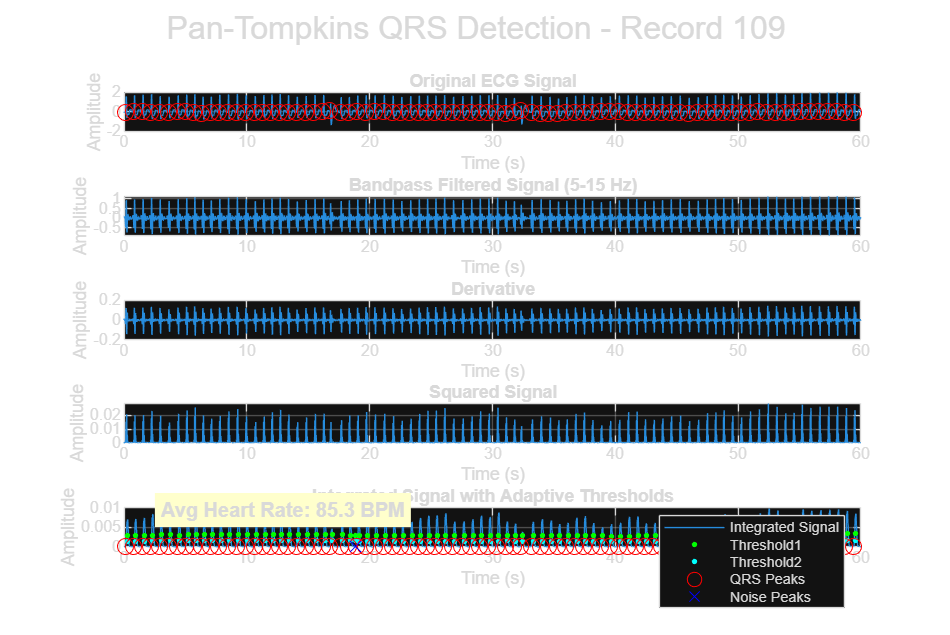



results = struct('record', {}, 'qrs_peaks', {}, 'annotations', {}, 'performance', {});

%% Process each record
for r = 1:length(record_numbers)
    record_num = record_numbers(r);
    fprintf('\nProcessing record %d (%d of %d)...\n', record_num, r, length(record_numbers));
    
    % Load the record data
    try
        [ecg_signal, record_fs, annotations] = load_mitbih_record_local(record_num, lead_number, start_time, duration);
        
        % Ensure we have ECG data
        if isempty(ecg_signal)
            warning('Record %d has no ECG data. Skipping...', record_num);
            continue;
        end
        
        fprintf('Loaded record %d: %d samples at %d Hz\n', record_num, length(ecg_signal), record_fs);
        
        % Run QRS detection
        [qrs_peaks, processed_ecg] = robust_pan_tompkins_qrs_detector_local(ecg_signal, record_fs, plot_individual);
        
        % Get QRS annotations (only those marked as normal beats 'N' or PVC 'V')
        ann_qrs = [];
        if ~isempty(annotations.time)
            % Extract beat annotations (N = normal, V = PVC, etc.)
            beat_annotations = ismember(annotations.type, {'N', 'V', 'L', 'R', 'A', 'a', 'J', 'S', 'F'});
            ann_qrs = annotations.time(beat_annotations);
        end
        
        % Evaluate detection performance
        if ~isempty(ann_qrs)
            [qrs_stats, performance] = evaluate_qrs_detection_local(qrs_peaks, ann_qrs, record_fs);
            
            % Store results
            results(r).record = record_num;
            results(r).qrs_peaks = qrs_peaks;
            results(r).annotations = ann_qrs;
            results(r).performance = performance;
            
            % Print performance metrics
            fprintf('Record %d Performance:\n', record_num);
            fprintf('  Sensitivity: %.2f%%\n', performance.sensitivity * 100);
            fprintf('  Positive Predictivity: %.2f%%\n', performance.positive_predictivity * 100);
            fprintf('  F1 Score: %.2f\n', performance.F1_score);
        else
            warning('No annotations found for record %d', record_num);
        end
        
        % Update figure title if individual plots are shown
        if plot_individual
            sgtitle(sprintf('Pan-Tompkins QRS Detection - Record %d', record_num), 'FontSize', 16);
        end
    catch ME
        warning('Error processing record %d: %s', record_num, ME.message);
        % Display the error stack for debugging
        disp(getReport(ME, 'extended'));
    end
end


%% Summarize overall performance
fprintf('\n===== OVERALL PERFORMANCE =====\n');


===== OVERALL PERFORMANCE =====


if ~isempty(results)
    % Check if all results have performance fields
    valid_results = arrayfun(@(x) isfield(x, 'performance') && ~isempty(x.performance), results);
    
    if any(valid_results)
        % Extract only valid results that have performance data
        valid_results_idx = find(valid_results);
        
        % Use cell arrays to collect the metrics
        sensitivity_values = cellfun(@(i) results(i).performance.sensitivity, num2cell(valid_results_idx));
        pp_values = cellfun(@(i) results(i).performance.positive_predictivity, num2cell(valid_results_idx));
        f1_values = cellfun(@(i) results(i).performance.F1_score, num2cell(valid_results_idx));
        
        fprintf('Average Sensitivity: %.2f%%\n', mean(sensitivity_values) * 100);
        fprintf('Average Positive Predictivity: %.2f%%\n', mean(pp_values) * 100);
        fprintf('Average F1 Score: %.2f\n', mean(f1_values));
        fprintf('Based on %d valid records out of %d total records\n', sum(valid_results), length(results));
    else
        fprintf('No valid performance results available.\n');
    end
else
    fprintf('No results available.\n');
end

No results available.



%% Show example with annotations and detections
if ~isempty(results) && length(results) >= 1
    % Select the first record with annotations for visualization
    record_idx = 1;
    
    % Load the record data again for visualization
    record_num = results(record_idx).record;
    [ecg_signal, ~, annotations] = load_mitbih_record_local(record_num, lead_number, start_time, duration);
    
    % Plot ECG with annotations and detections
    t = (0:length(ecg_signal)-1)/fs;
    
    figure('Name', sprintf('Record %d Annotation Comparison', record_num), 'Position', [100, 100, 1200, 600]);
    plot(t, ecg_signal, 'b');
    hold on;
    
    % Plot QRS detections
    qrs_peaks = results(record_idx).qrs_peaks;
    plot(qrs_peaks/fs, ecg_signal(qrs_peaks), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
    
    % Plot annotations
    ann_qrs = results(record_idx).annotations;
    plot(ann_qrs/fs, ecg_signal(ann_qrs), 'gx', 'MarkerSize', 10, 'LineWidth', 2);
    
    title(sprintf('Record %d: QRS Detection vs Annotations', record_num), 'FontSize', 14);
    xlabel('Time (s)', 'FontSize', 12);
    ylabel('Amplitude', 'FontSize', 12);
    legend('ECG Signal', 'QRS Detections', 'Reference Annotations');
    grid on;
    
    % Add performance text
    perf = results(record_idx).performance;
    text_str = sprintf(['Sensitivity: %.2f%%\nPositive Predictivity: %.2f%%\n' ...
                       'F1 Score: %.2f'], ...
                       perf.sensitivity * 100, perf.positive_predictivity * 100, perf.F1_score);
    annotation('textbox', [0.15, 0.75, 0.2, 0.15], 'String', text_str, ...
               'EdgeColor', 'none', 'BackgroundColor', [1 1 0.8], ...
               'FontSize', 12, 'FontWeight', 'bold');
end

%% ===== LOCAL FUNCTION DEFINITIONS =====

function [qrs_peaks, processed_ecg] = robust_pan_tompkins_qrs_detector_local(ecg_signal, fs, plot_results)
% ROBUST_PAN_TOMPKINS_QRS_DETECTOR_LOCAL QRS complex detection optimized for MIT-BIH Database
%   [QRS_PEAKS, PROCESSED_ECG] = ROBUST_PAN_TOMPKINS_QRS_DETECTOR_LOCAL(ECG_SIGNAL, FS, PLOT_RESULTS) 
%   detects QRS complexes in the ECG signal using an enhanced Pan-Tompkins algorithm.

% Handle input arguments
if nargin < 1
    error('ECG signal is required');
end
if nargin < 2 || isempty(fs)
    fs = 360; % Default sampling frequency for MIT-BIH database
    fprintf('Using default sampling frequency of 360 Hz (MIT-BIH standard)\n');
end
if nargin < 3
    plot_results = true;
end

% Remove NaN and Inf values
ecg_signal(isnan(ecg_signal) | isinf(ecg_signal)) = 0;

% Detrend to remove baseline wandering
ecg_signal = detrend(ecg_signal);

% Parameters for Pan-Tompkins algorithm (optimized for MIT-BIH)
integration_window = round(0.150 * fs);    % 150 ms window
filter_delay = round(0.2 * fs);            % Filter delay compensation
refractory_period = round(0.2 * fs);       % 200 ms refractory period
learning_rate_signal = 0.125;              % Learning rate for signal peak
learning_rate_noise = 0.125;               % Learning rate for noise peak
signal_threshold_weight = 0.25;            % Signal threshold weight
noise_threshold_weight = 0.5;              % Secondary threshold weight

% Initialize output structure
processed_ecg = struct();
processed_ecg.original = ecg_signal;

% ===== STAGE 1: Bandpass Filtering (5-15 Hz) =====
% Create bandpass filter more suitable for MIT-BIH database
lowcut = 5;    % 5Hz cutoff for high-pass
highcut = 15;  % 15Hz cutoff for low-pass
wn = [lowcut highcut] / (fs/2);
[b, a] = butter(4, wn, 'bandpass');
bandpass_signal = filtfilt(b, a, ecg_signal); % Zero-phase filtering
processed_ecg.bandpass = bandpass_signal;

% ===== STAGE 2: Derivative ======
% Five-point derivative
b = [1 2 0 -2 -1] * (1/8);
a = 1;
derivative_signal = filter(b, a, bandpass_signal);
processed_ecg.derivative = derivative_signal;

% ===== STAGE 3: Squaring ======
squared_signal = derivative_signal.^2;
processed_ecg.squared = squared_signal;

% ===== STAGE 4: Moving Window Integration ======
b = ones(1, integration_window)/integration_window;
a = 1;
integrated_signal = filter(b, a, squared_signal);
processed_ecg.integrated = integrated_signal;

% ===== STAGE 5: Adaptive Thresholding and Peak Detection ======
% Initialize variables for adaptive thresholding
qrs_peaks = [];
noise_peaks = [];
SPKI = 0;      % Signal peak level
NPKI = 0;      % Noise peak level
threshold1 = 0; % First threshold
threshold2 = 0; % Second threshold

% Initial learning phase to set thresholds
learn_phase_duration = round(2 * fs); % 2 seconds learning
if length(integrated_signal) >= learn_phase_duration
    learn_segment = integrated_signal(1:learn_phase_duration);
    SPKI = mean(learn_segment) + 2*std(learn_segment);
    NPKI = mean(learn_segment);
    threshold1 = NPKI + signal_threshold_weight * (SPKI - NPKI);
    threshold2 = noise_threshold_weight * threshold1;
end

% Store adaptive thresholds for plotting
thresholds = zeros(size(integrated_signal));
thresholds2 = zeros(size(integrated_signal));

% Find all local maxima in the integrated signal using a sliding window
window_size = round(0.1 * fs); % 100 ms window
peak_candidates = [];
peak_values = [];

for i = window_size+1 : length(integrated_signal)-window_size
    window = integrated_signal(i-window_size:i+window_size);
    if integrated_signal(i) == max(window) && integrated_signal(i) > 0
        peak_candidates = [peak_candidates, i];
        peak_values = [peak_values, integrated_signal(i)];
    end
end

% Process each detected peak candidate
last_qrs = -refractory_period;
threshold_history = zeros(length(peak_candidates), 2);

for i = 1:length(peak_candidates)
    loc = peak_candidates(i);
    peak_val = peak_values(i);
    
    % Store current thresholds
    thresholds(loc) = threshold1;
    thresholds2(loc) = threshold2;
    threshold_history(i,:) = [threshold1, threshold2];
    
    % Check if this peak is within refractory period
    if loc - last_qrs <= refractory_period
        % Update noise peak
        NPKI = learning_rate_noise * peak_val + (1-learning_rate_noise) * NPKI;
        noise_peaks = [noise_peaks, loc];
        continue;
    end
    
    % Classify peak as QRS or noise
    if peak_val > threshold1
        % This is a QRS complex
        qrs_peaks = [qrs_peaks, loc-filter_delay]; % Compensate for filter delay
        last_qrs = loc;
        
        % Update signal peak
        SPKI = learning_rate_signal * peak_val + (1-learning_rate_signal) * SPKI;
    else
        % This is likely noise
        noise_peaks = [noise_peaks, loc];
        
        % Update noise peak
        NPKI = learning_rate_noise * peak_val + (1-learning_rate_noise) * NPKI;
    end
    
    % Update thresholds
    threshold1 = NPKI + signal_threshold_weight * (SPKI - NPKI);
    threshold2 = noise_threshold_weight * threshold1;
end

% Final check for missed beats using RR interval analysis
if ~isempty(qrs_peaks)
    % Calculate RR intervals
    RR = diff(qrs_peaks);
    mean_RR = mean(RR);
    missed_beats = [];
    
    % Check for missed beats (when RR interval is > 1.5x the mean RR)
    for i = 1:length(RR)
        if RR(i) > 1.8 * mean_RR
            % Potential missed beat in this interval
            search_start = qrs_peaks(i);
            search_end = qrs_peaks(i+1);
            
            % Look for possible peaks in this range that were classified as noise
            for j = 1:length(noise_peaks)
                if noise_peaks(j) > search_start && noise_peaks(j) < search_end
                    missed_peak_val = integrated_signal(noise_peaks(j));
                    % Check if this peak would pass with a lower threshold
                    if missed_peak_val > 0.5 * threshold1
                        missed_beats = [missed_beats, noise_peaks(j)-filter_delay];
                    end
                end
            end
        end
    end
    
    % Add missed beats to QRS peaks
    qrs_peaks = sort([qrs_peaks, missed_beats]);
end

% Ensure QRS peak indices are within valid range
qrs_peaks = qrs_peaks(qrs_peaks > 0 & qrs_peaks <= length(ecg_signal));

% Store results in output structure
processed_ecg.qrs_peaks = qrs_peaks;
processed_ecg.threshold1 = thresholds;
processed_ecg.threshold2 = thresholds2;
processed_ecg.noise_peaks = noise_peaks;

% Plot results if requested
if plot_results
    t = (0:length(ecg_signal)-1)/fs;
    
    figure('Name', 'Pan-Tompkins QRS Detection', 'NumberTitle', 'off', 'Position', [100, 100, 1200, 800]);
    
    % Plot original signal
    subplot(5,1,1);
    plot(t, ecg_signal);
    title('Original ECG Signal');
    hold on;
    if ~isempty(qrs_peaks)
        valid_peaks = qrs_peaks(qrs_peaks > 0 & qrs_peaks <= length(ecg_signal));
        plot(valid_peaks/fs, ecg_signal(valid_peaks), 'ro', 'MarkerSize', 8);
    end
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
    
    % Plot bandpass filtered signal
    subplot(5,1,2);
    plot(t, processed_ecg.bandpass);
    title('Bandpass Filtered Signal (5-15 Hz)');
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
    
    % Plot derivative
    subplot(5,1,3);
    plot(t, processed_ecg.derivative);
    title('Derivative');
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
    
    % Plot squared signal
    subplot(5,1,4);
    plot(t, processed_ecg.squared);
    title('Squared Signal');
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
    
    % Plot integrated signal with thresholds
    subplot(5,1,5);
    plot(t, processed_ecg.integrated);
    title('Integrated Signal with Adaptive Thresholds');
    hold on;
    
    % Plot thresholds where they were calculated
    non_zero_idx = find(thresholds > 0);
    if ~isempty(non_zero_idx)
        plot(non_zero_idx/fs, thresholds(non_zero_idx), 'g.', 'MarkerSize', 8);
        plot(non_zero_idx/fs, thresholds2(non_zero_idx), 'c.', 'MarkerSize', 8);
    end
    
    % Plot detected QRS peaks
    if ~isempty(qrs_peaks)
        valid_peaks = qrs_peaks(qrs_peaks > 0 & qrs_peaks <= length(processed_ecg.integrated));
        plot(valid_peaks/fs, processed_ecg.integrated(valid_peaks), 'ro', 'MarkerSize', 8);
    end
    
    % Plot noise peaks
    if ~isempty(noise_peaks)
        valid_noise = noise_peaks(noise_peaks > 0 & noise_peaks <= length(processed_ecg.integrated));
        plot(valid_noise/fs, processed_ecg.integrated(valid_noise), 'bx', 'MarkerSize', 8);
    end
    
    legend('Integrated Signal', 'Threshold1', 'Threshold2', 'QRS Peaks', 'Noise Peaks');
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
    
    % Add heart rate display
    if ~isempty(qrs_peaks) && length(qrs_peaks) > 1
        RR = diff(qrs_peaks)/fs;
        HR = 60./RR;
        avg_HR = mean(HR);
        text(0.05, 0.95, sprintf('Avg Heart Rate: %.1f BPM', avg_HR), ...
            'Units', 'normalized', 'FontWeight', 'bold', 'BackgroundColor', [1 1 0.8]);
    end
    
    % Make the figure nicer
    set(gcf, 'Color', 'white');
    sgtitle('Pan-Tompkins QRS Detection Algorithm Results', 'FontSize', 16);
end
end

function [record_data, fs, ann] = load_mitbih_record_local(record_num, lead_num, start_time, duration)
% LOAD_MITBIH_RECORD_LOCAL Load ECG data from MIT-BIH Arrhythmia Database
%   [RECORD_DATA, FS, ANN] = LOAD_MITBIH_RECORD_LOCAL(RECORD_NUM, LEAD_NUM, START_TIME, DURATION)
%   loads the specified record from the MIT-BIH Arrhythmia Database.

% Check if WFDB Toolbox is installed
if ~exist('rdann', 'file') || ~exist('rdsamp', 'file')
    error(['WFDB Toolbox not found. Please install it from: ' ...
           'https://physionet.org/content/wfdb-matlab/0.10.0/']);
end

% Handle default values
if nargin < 2 || isempty(lead_num)
    lead_num = 1;
end
if nargin < 3 || isempty(start_time)
    start_time = 0;
end
if nargin < 4 
    duration = [];  % Empty duration means load the entire record
end

% Construct record name
record_name = sprintf('%03d', record_num);

try
    % Convert start_time and duration to samples
    fs = 360;  % MIT-BIH sampling frequency
    start_sample = round(start_time * fs);
    
    if isempty(duration)
        % Load entire record
        [signal, ~, ~] = rdsamp(['mitdb/' record_name], lead_num);
        end_sample = length(signal);
    else
        end_sample = start_sample + round(duration * fs);
        % Load specified portion of the record
        [signal, ~, ~] = rdsamp(['mitdb/' record_name], lead_num, end_sample, start_sample);
    end
    
    % Load annotations
    try
        ann = rdann(['mitdb/' record_name], 'atr', 'from', start_sample, 'to', end_sample);
        % Adjust annotation indices for the extraction window
        ann.time = ann.time - start_sample;
    catch
        warning('Could not load annotations. Returning empty annotation structure.');
        ann = struct('time', [], 'type', []);
    end
    
    % Extract the signal for the specified lead
    record_data = signal;
    
catch ME
    error(['Error loading record: ', ME.message, '\n', ...
           'Ensure you have downloaded the MIT-BIH database and ', ...
           'it is in your MATLAB path or current directory.']);
end
end

function [qrs_stats, detection_performance] = evaluate_qrs_detection_local(detected_qrs, annotation_qrs, fs, window_size)
% EVALUATE_QRS_DETECTION_LOCAL Evaluate QRS detection against annotations
%   [QRS_STATS, DETECTION_PERFORMANCE] = EVALUATE_QRS_DETECTION_LOCAL(DETECTED_QRS, ANNOTATION_QRS, FS, WINDOW_SIZE)
%   evaluates QRS detection performance against reference annotations.

% Default window size is 100 ms if not specified
if nargin < 4 || isempty(window_size)
    window_size = 0.1; % 100 ms
end

% Convert window size from seconds to samples
window_samples = round(window_size * fs);

% Initialize counters
true_positives = 0;
matched_ann = false(size(annotation_qrs));
matched_det = false(size(detected_qrs));

% Loop through annotation QRS complexes
for i = 1:length(annotation_qrs)
    % Find detected QRS within the window
    for j = 1:length(detected_qrs)
        if ~matched_det(j) && abs(detected_qrs(j) - annotation_qrs(i)) <= window_samples
            true_positives = true_positives + 1;
            matched_ann(i) = true;
            matched_det(j) = true;
            break;
        end
    end
end

% Calculate statistics
false_positives = sum(~matched_det);
false_negatives = sum(~matched_ann);

% Build output structures
qrs_stats = struct(...
    'true_positives', true_positives, ...
    'false_positives', false_positives, ...
    'false_negatives', false_negatives);

% Calculate performance metrics
sensitivity = true_positives / (true_positives + false_negatives);
if (true_positives + false_positives) > 0
    positive_predictivity = true_positives / (true_positives + false_positives);
else
    positive_predictivity = 0;
end

% F1 score
if (sensitivity + positive_predictivity) > 0
    F1_score = 2 * (sensitivity * positive_predictivity) / (sensitivity + positive_predictivity);
else
    F1_score = 0;
end

detection_performance = struct(...
    'sensitivity', sensitivity, ...
    'positive_predictivity', positive_predictivity, ...
    'F1_score', F1_score);
end

https://app.presentations.ai/view/ahfVnZ